Looks at the distribution of mins for different clean parameters

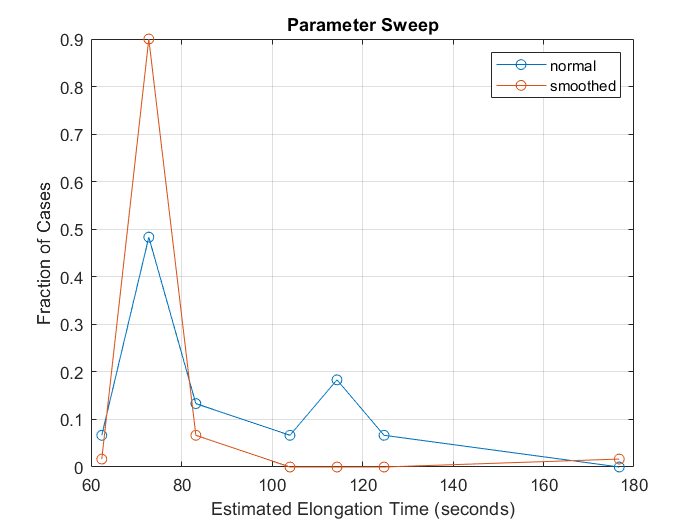

% looks at overall distribution

all_data = load("1_9kb_fluo3DN_06_13_21.mat");
all_data = all_data.all_data;
all_data = all_data([all_data.num_traces] > 0);
time_res = unique([all_data.time_res]);
type = 'r4_min3';

all_mins = [all_data.(type)];
all_mins_s = [all_data.([type '_s'])];

all_poss = unique([all_mins all_mins_s]);
nums = zeros(1, length(all_poss));
nums_s = zeros(1, length(all_poss));
for i = 1:length(all_poss)
    nums(i) = length(find(all_mins == all_poss(i))) / length(all_mins);
    nums_s(i) = length(find(all_mins_s == all_poss(i))) / length(all_mins_s); 
end

figure();
plot(all_poss * time_res, nums, 'o-');
hold on
plot(all_poss * time_res, nums_s, 'o-');
grid on
xlabel('Estimated Elongation Time (seconds)');
ylabel('Fraction of Cases')
title('Parameter Sweep')
legend('normal', 'smoothed')

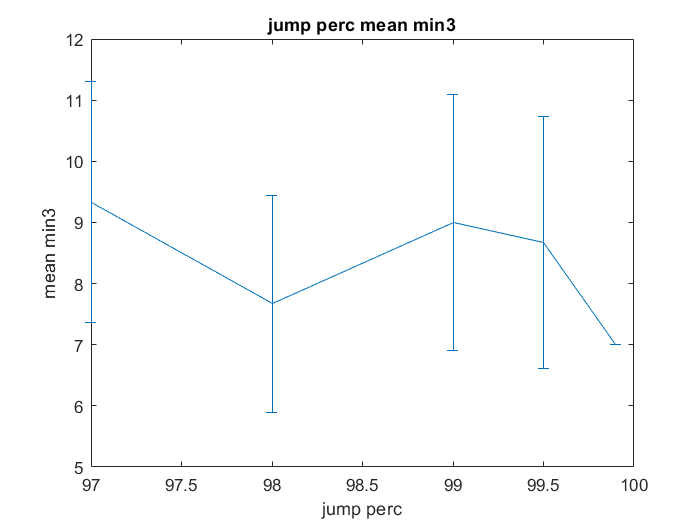


% looks at mean/sd value across jump percentages
jumps = sort(unique([all_data.jump_perc]));
means = [];
sds = [];
for jump = jumps
    some_data = all_data([all_data.jump_perc] == jump);
    means = [means mean([some_data.(type)])];
    sds = [sds std([some_data.(type)])];
end
figure();
errorbar(jumps, means, sds);
xlabel('jump perc')
ylabel('mean min3');
title('jump perc mean min3')

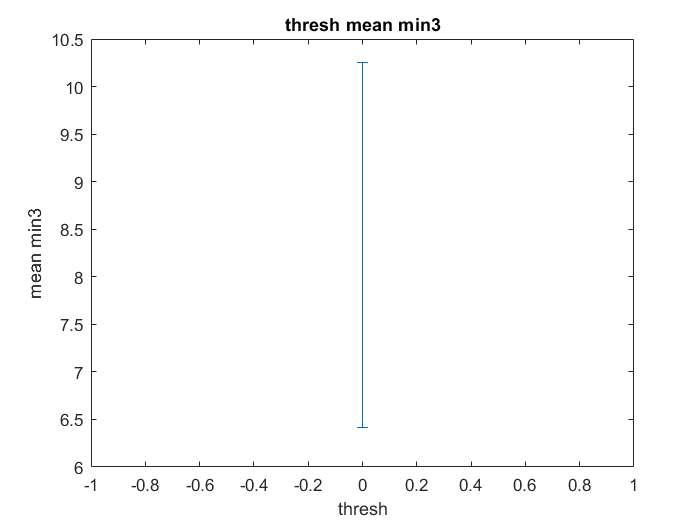


% looks at mean/sd value across thresh
threshes = sort(unique([all_data.thresh]));
means = [];
sds = [];
for thresh= threshes
    some_data = all_data([all_data.thresh] == thresh);
    means = [means mean([some_data.(type)])];
    sds = [sds std([some_data.(type)])];
end
figure();
errorbar(threshes, means, sds);
xlabel('thresh')
ylabel('mean min3');
title('thresh mean min3')

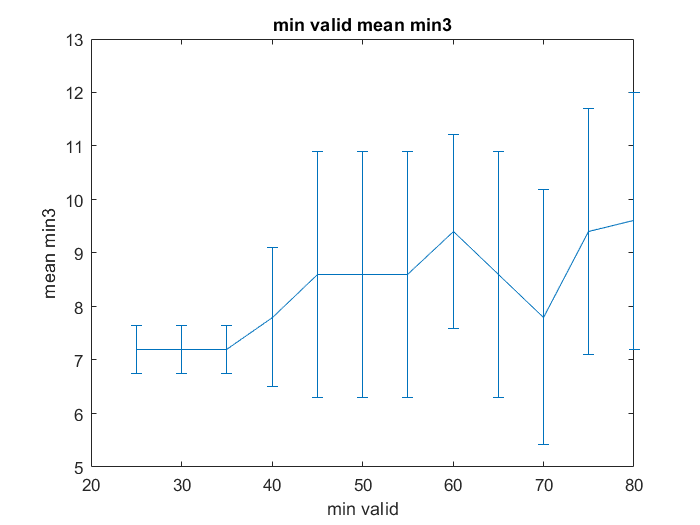


% looks at mean/sd value across min_valids
% looks at mean/sd value across thresh
min_valids = sort(unique([all_data.min_valid]));
means = [];
sds = [];
for min_valid= min_valids
    some_data = all_data([all_data.min_valid] == min_valid);
    means = [means mean([some_data.(type)])];
    sds = [sds std([some_data.(type)])];
end
figure();
errorbar(min_valids, means, sds);
xlabel('min valid')
ylabel('mean min3');
title('min valid mean min3')

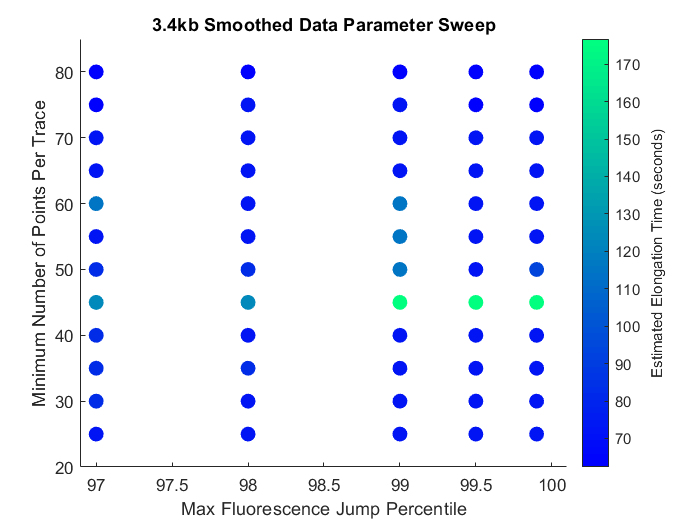

% makes scatter plot where each color is a different estimate

all_data = load("1_9kb_fluo3DN_04_24_21.mat");
all_data = all_data.all_data;
type = 'r1_min3_s';
target_val = 12;
time_res = unique([all_data.time_res]);

figure();

for idx = 1:length(all_data)
    if all_data(idx).(type) == target_val
        my_color = 'blue';
    elseif all_data(idx).(type) > target_val
        my_color = 'green';
    else
        my_color = 'red';
    end
    scatter(all_data(idx).jump_perc, all_data(idx).min_valid,80, ...
        all_data(idx).(type)*time_res, 'filled');    
    %scatter(all_data(idx).jump_perc, all_data(idx).min_valid,40, ...
    %    all_data(idx).r4_min3);
    hold on
end
colormap winter;
c = colorbar;
c.Label.String = 'Estimated Elongation Time (seconds)';
xlim([96.9,100.1])
ylim([20,85])

xlabel('Max Fluorescence Jump Percentile');
ylabel('Minimum Number of Points Per Trace');
title('3.4kb Smoothed Data Parameter Sweep')

Looks at simulated data autocorrelation elongation analysis

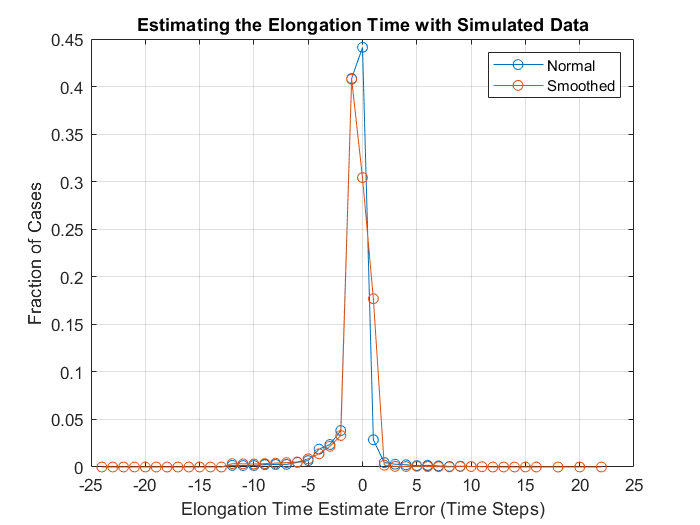

all_data = load("../test_theories/simulated_cleaning_06_13_21.mat");
all_data = all_data.all_data;
%all_data = all_data([all_data.num_traces] > 20);


diffs = [all_data.min3] - [all_data.T];
diffs_s = [all_data.min3_s] - [all_data.T];

all_poss = sort(unique(diffs + diffs_s));
normal_vals = zeros(size(all_poss));
smooth_vals = zeros(size(all_poss));
for i = 1:length(all_poss)
    normal_vals(i) = length(find([diffs] == all_poss(i))) / length(diffs);
    smooth_vals(i) = length(find(diffs_s == all_poss(i))) / length(diffs_s);
end

figure();
plot(all_poss, normal_vals, 'o-');
hold on
plot(all_poss, smooth_vals, 'o-');
xlabel('Elongation Time Estimate Error (Time Steps)');
ylabel('Fraction of Cases');
title('Estimating the Elongation Time with Simulated Data')
legend({'Normal', 'Smoothed'});
grid on

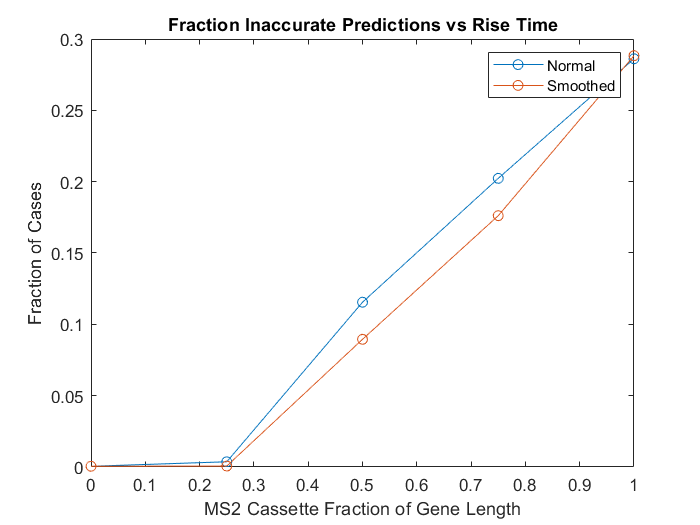


shit_data = all_data(find(abs(diffs) >= 2));

% looks for particular parameters that are influential 
a_data = zeros(1,length(unique([all_data.a0])));
a_data_s = zeros(1,length(unique([all_data.a0])));
a_vals = sort(unique([all_data.a0]));
for i = 1:length(a_data)
    temp_data = all_data([all_data.a0] == a_vals(i));
    a_diffs = [temp_data.min3] - [temp_data.T];
    a_diffs_s = [temp_data.min3_s] - [temp_data.T];
    a_data(i) = sum(abs(a_diffs) > 1) / length(a_diffs);
    a_data_s(i) = sum(abs(a_diffs_s) > 1) / length(a_diffs_s);
end
figure()
plot(a_vals, a_data, 'o-');
hold on
plot(a_vals, a_data_s, 'o-');
xlabel('MS2 Cassette Fraction of Gene Length');
ylabel('Fraction of Cases');
legend({'Normal', 'Smoothed'});
title('Fraction Inaccurate Predictions vs Rise Time');

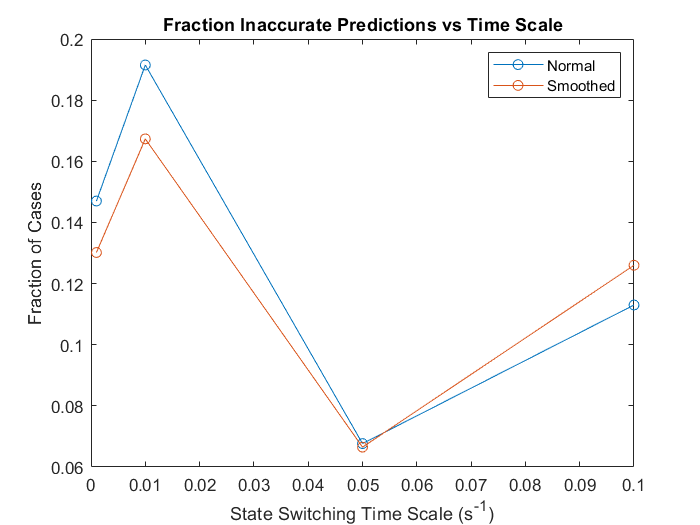


k_vals = [0.001, 0.01, 0.05, 0.1];
k_data = zeros(1,length(k_vals));
k_data_s = zeros(1,length(k_vals));
for i = 1:length(k_data)
    R = [-k_vals(i), k_vals(i); k_vals(i), -k_vals(i)];
    temp_data = all_data([temp_data.min3] == -1);
    idx = 1;
    for dat=all_data
        if dat.R == R
            temp_data(idx) = dat;
            idx = idx + 1;
        end
    end
    k_diffs = [temp_data.min3] - [temp_data.T];
    k_diffs_s = [temp_data.min3_s] - [temp_data.T];
    k_data(i) = sum(abs(k_diffs) > 1) / length(k_diffs);
    k_data_s(i) = sum(abs(k_diffs_s) > 1) / length(k_diffs_s);
end
figure()
plot(k_vals, k_data, 'o-');
hold on
plot(k_vals, k_data_s, 'o-');
xlabel('State Switching Time Scale (s^{-1})');
ylabel('Fraction of Cases');
legend({'Normal', 'Smoothed'});
title('Fraction Inaccurate Predictions vs Time Scale');

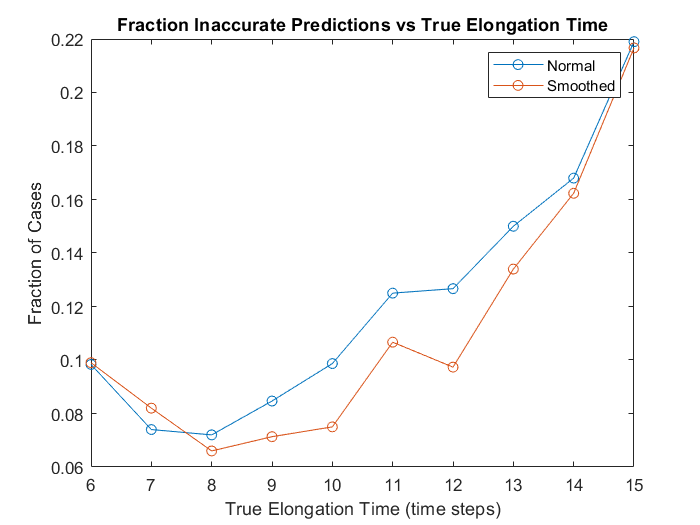


T_vals = unique([all_data.T]);
T_data = zeros(1,length(T_vals));
T_data_s = zeros(1,length(T_vals));
for i = 1:length(T_data)
    temp_data = all_data([all_data.T] == T_vals(i));
    T_diffs = [temp_data.min3] - [temp_data.T];
    T_diffs_s = [temp_data.min3_s] - [temp_data.T];
    T_data(i) = sum(abs(T_diffs) > 1) / length(T_diffs);
    T_data_s(i) = sum(abs(T_diffs_s) > 1) / length(T_diffs);
end
figure()
plot(T_vals, T_data, 'o-');
hold on
plot(T_vals, T_data_s, 'o-');
xlabel('True Elongation Time (time steps)');
ylabel('Fraction of Cases');
legend({'Normal', 'Smoothed'});
title('Fraction Inaccurate Predictions vs True Elongation Time');

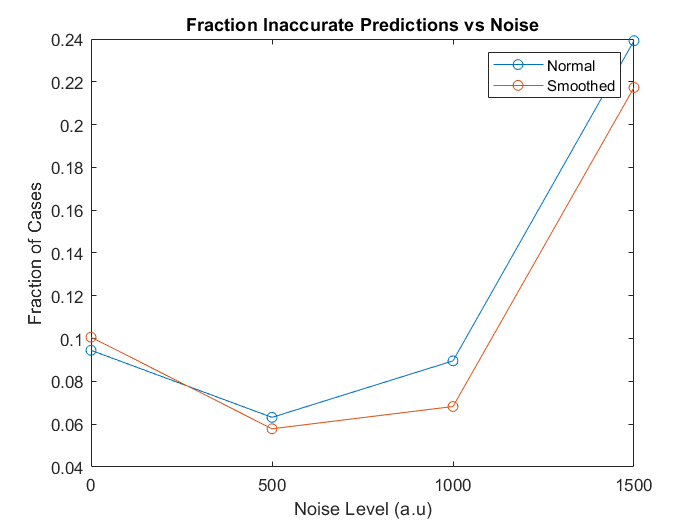


n_vals = unique([all_data.noise]);
n_data = zeros(1,length(n_vals));
n_data_s = zeros(1,length(n_vals));
for i = 1:length(n_data)
    temp_data = all_data([all_data.noise] == n_vals(i));
    n_diffs = [temp_data.min3] - [temp_data.T];
    n_diffs_s = [temp_data.min3_s] - [temp_data.T];
    n_data(i) = sum(abs(n_diffs) > 1) / length(n_diffs);
    n_data_s(i) = sum(abs(n_diffs_s) > 1) / length(n_diffs_s);
end
figure()
plot(n_vals, n_data, 'o-');
hold on
plot(n_vals, n_data_s, 'o-');
xlabel('Noise Level (a.u)');
ylabel('Fraction of Cases');
legend({'Normal', 'Smoothed'});
title('Fraction Inaccurate Predictions vs Noise')